# Лабораторная работа №2

Размер матрицы: 

n = 10;

Число обусловленности:

alpha = 4;
[A, B, X0] = gen_matr(n, alpha);
X = matr_solve(A, B);
norm(X-X0)

ans = 0.0013

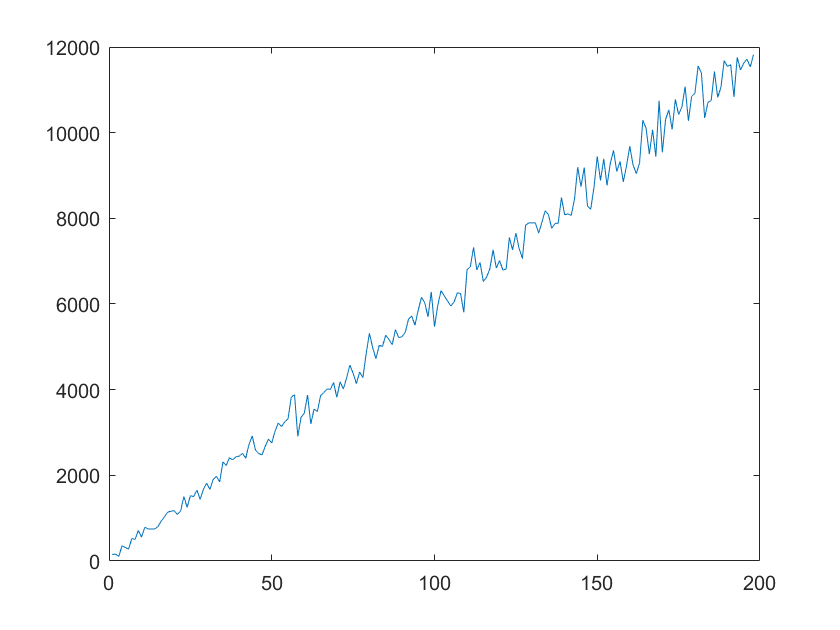


N = [];
min = 2;
max = 200;
step = 1;
coa = fix((max-min)/step);

for i = 1:coa
    n = min + i*step;
    X0 = [];
    for j = 1:n
        X0(j) = randi(100);
    end
    H = hilb(n);
    %[H, B, X0] = gen_matr(100, n);
    B = H*X0';
    X = matr_solve(H, B);
    N(i) = norm(X-X0);
end

figure
plot(N)

function [A, B, V1] = gen_matr(n, alpha);
    D = eye(n);
    D(1, 1) = alpha;
    V = [];
    V1 = [];
    for i = 1:n
        V1(i) = randi(1000);
        V(i) = randi(1000);
    end
    Q = eye(n) - 2*(V-V')/(norm(V))^2;
    A = Q*D*Q';
    B = A*V1';
    V1 = V1';
end

function [L, D, R] = LDR(A)
    n = length(A);
    [L, U] = lu(A);
    d = [];
    R = eye(n);
    d(1) = A(1, 1);
    for i = 1:n
        O = 0;
        for j = 1:i-1
            O = O + L(i, j)*d(j)*R(j, i);
        end
        d(i) = A(i, i) - O;
        O = 0;
        for j = i:n
            for k = j:i-1
                O = O + L(i, k)*d(k)*R(k, j);
            end
            R(i, j) = (A(i, j) - O)/d(i);
        end
    end
    D = diag(d, 0);
end

function X = matr_solve(A, B)
    [L, D, R] = LDR(A);
    Z = inv(L)*B;
    Y = inv(D)*Z;
    X = inv(R)*Y;
end